clf

% boilerplate
mm_to_m = 1/1000;

constants = containers.Map;
constants('youngs_mod') = 29*10^9;%5*10^9%25*10^9 %29*10^9;%250*10^9;
constants('shear_mod') = 10*10^9;%1.9*10^9%10*10^9;
constants('shape_factor') = 6/5;

forces = containers.Map();
F = 300;
Fa = 90*(pi/180); 
V = F*sin(Fa); 
H = F*cos(Fa);
forces('f') = [V; H];

% spring specs
% FOR A CURVED SECTION, THE  start_angle IS THE LOADED END
c1 = containers.Map();
c1('length') = 150*mm_to_m;
c1('height') = 25*mm_to_m;
c1('thickness') = 6*mm_to_m;
c1('width') = 60*mm_to_m;
c1('chord') = sqrt(c1('height')^2+c1('length')^2);

c1('radius') = 0.9128; %m
c1('sweep_angle') = 2*asin(0.5*c1('chord')/c1('radius'));

c1('start_angle') = -pi/2;
c1('end_angle') = -pi/2+0.1651;
c1('boundary_angle') = 0;
c1('boundary_defV') = 0;
c1('boundary_defH') = 0;
c1('couple') = 0; % init
curved = Curved(constants, c1);


s1 = containers.Map;
s1('thickness') = 6*mm_to_m;
s1('length') = (-125)*mm_to_m;
s1('width') = 60*mm_to_m;
s1('beam_angle') = 0.1651; %*(pi/180); % rad
s1('couple') = 0; % init
s1('boundary_angle') = 0;
s1('boundary_defV') = 0;
s1('boundary_defH') = 0;
straight1 = Straight(constants, s1);

sections = containers.Map();
sections('1') = straight1;
sections('2') = curved;

% implement force sweep where range input is magnitude and angle sweep
[x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e, stiffness] = stitch_sweep(sections, forces, 'end_angle', 10, [-pi/2+0.1, -pi/2+0.5], 'linspace');

% [x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e, stiffness] = stitch(sections, forces, 'linspace');
disp(round(stiffness))

$$\left(\begin{array}{c} 280\\ 242\\ 205\\ 178\\ 159\\ 143\\ 130\\ 120\\ 111\\ 103 \end{array}\right)$$

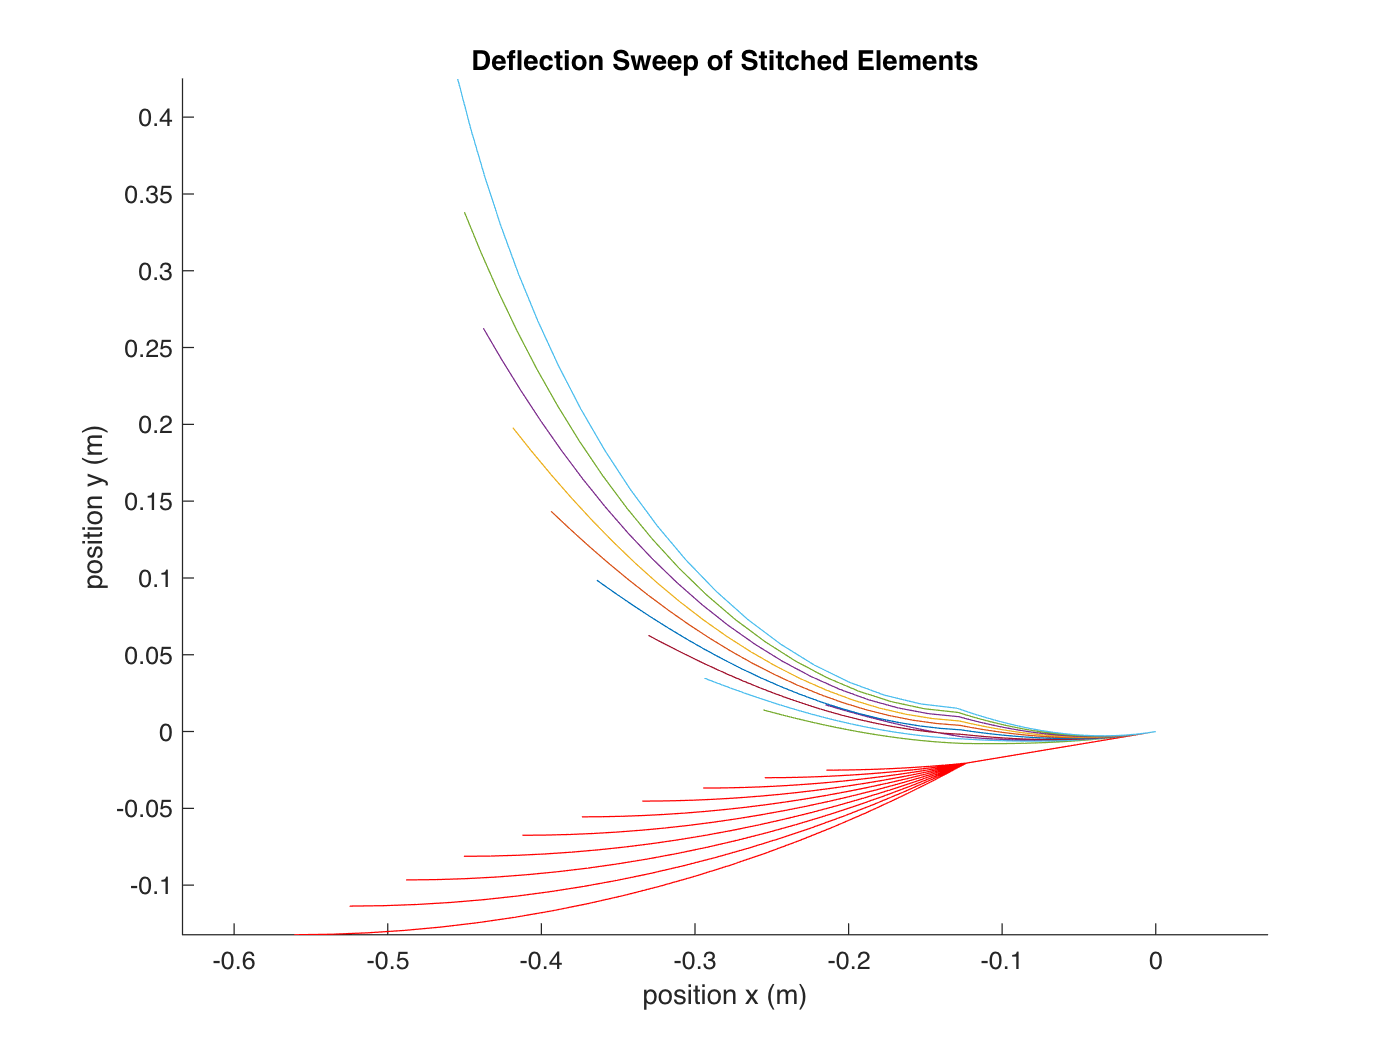

hold on
axis('equal')
% plot(x_base(1, :), y_base(1, :),'red')
plot(x_base(:, :)', y_base(:, :)', 'red')
plot(x_deformed(:, :)', y_deformed(:, :)')
title('Deflection Sweep of Stitched Elements')
xlabel('position x (m)')
ylabel('position y (m)')
hold off

% plot(x_base(:, :)', moment(:, :)', 'red')

% plot(x_deformed(1, :), y_deformed(1, :))

% pos = [x_base(end); y_base(end); 0];
% posD = [x_deformed(end); y_deformed(end); 0];
% rad_vec = atan2(norm(cross(pos,posD)),dot(pos,posD));
% stiff = moment(1)/rad_vec
% 
% title('deflection')
% plot(x_base, y_base)
% hold on
% plot(x_deformed, y_deformed)
% xlabel('m')
% ylabel('m')
% legend('static', 'deformed', location='southeastoutside')
% axis('equal')
% hold off
% 
% plot(x_base, moment)
% title('moment') 
% plot(x_base, ang)
% title('angle')
% plot(x_base, strain_e)
% title('energy')